a=1+mod(112,3);
t=[-1:0.001:1];
y1=sin(20*pi*a*t)

y1 =     0.0000    0.1253    0.2487    0.3681    0.4818    0.5878    0.6845    0.7705    0.8443    0.9048    0.9511    0.9823    0.9980    0.9980    0.9823    0.9511    0.9048    0.8443    0.7705    0.6845    0.5878    0.4818    0.3681    0.2487    0.1253   -0.0000   -0.1253   -0.2487   -0.3681   -0.4818   -0.5878   -0.6845   -0.7705   -0.8443   -0.9048   -0.9511   -0.9823   -0.9980   -0.9980   -0.9823   -0.9511   -0.9048   -0.8443   -0.7705   -0.6845   -0.5878   -0.4818   -0.3681   -0.2487   -0.1253


subplot(2,2,1)
plot(t,y1)
y2=cos(5*pi*a*t+(pi/4))

y2 =     0.7071    0.6845    0.6613    0.6374    0.6129    0.5878    0.5621    0.5358    0.5090    0.4818    0.4540    0.4258    0.3971    0.3681    0.3387    0.3090    0.2790    0.2487    0.2181    0.1874    0.1564    0.1253    0.0941    0.0628    0.0314   -0.0000   -0.0314   -0.0628   -0.0941   -0.1253   -0.1564   -0.1874   -0.2181   -0.2487   -0.2790   -0.3090   -0.3387   -0.3681   -0.3971   -0.4258   -0.4540   -0.4818   -0.5090   -0.5358   -0.5621   -0.5878   -0.6129   -0.6374   -0.6613   -0.6845


subplot(2,2,2)
plot(t,y2)
y3=exp(-2*a*t)

y3 =    54.5982   54.3802   54.1631   53.9469   53.7315   53.5170   53.3034   53.0906   52.8787   52.6676   52.4573   52.2479   52.0393   51.8316   51.6247   51.4186   51.2133   51.0089   50.8053   50.6025   50.4004   50.1992   49.9988   49.7993   49.6005   49.4024   49.2052   49.0088   48.8132   48.6183   48.4242   48.2309   48.0384   47.8466   47.6556   47.4654   47.2759   47.0871   46.8992   46.7119   46.5255   46.3397   46.1548   45.9705   45.7870   45.6042   45.4222   45.2408   45.0602   44.8803


subplot(2,2,3)
plot(t,y3)
y4=(exp(-0.25*a*t)).*(sin(20*pi*t))

y4 =     0.0000    0.1035    0.2064    0.3085    0.4092    0.5082    0.6051    0.6995    0.7911    0.8795    0.9643    1.0452    1.1219    1.1941    1.2615    1.3239    1.3810    1.4326    1.4784    1.5184    1.5524    1.5802    1.6018    1.6170    1.6258    1.6282    1.6242    1.6138    1.5970    1.5739    1.5447    1.5094    1.4681    1.4211    1.3686    1.3107    1.2477    1.1798    1.1074    1.0306    0.9499    0.8655    0.7778    0.6871    0.5937    0.4981    0.4007    0.3018    0.2017    0.1010


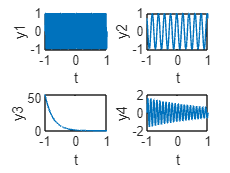

subplot(2,2,4)
plot(t,y4)

subplot(2,2,1)
xlabel("t")
ylabel("y1")

subplot(2,2,2)
xlabel("t")
ylabel("y2")
subplot(2,2,3)
xlabel("t")
ylabel("y3")
subplot(2,2,4)
xlabel("t")
ylabel("y4")

a=1+mod(112,3);
t=[-5:0.001:5];
x=inline('exp(-2*t)','t')

x =

     Inline function:
     x(t) = exp(-2*t)



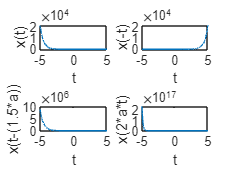

subplot(2,2,1)
plot(t,x(t))
subplot(2,2,2)
plot(t,x(-t))
subplot(2,2,3)
plot(t,x(t-(1.5*a)))
subplot(2,2,4)
plot(t,x(2*a*t))

subplot(2,2,1)
xlabel("t")
ylabel("x(t)")
subplot(2,2,2)
xlabel("t")
ylabel("x(-t)")
subplot(2,2,3)
xlabel("t")
ylabel("x(t-(1.5*a))")
subplot(2,2,4)
xlabel("t")
ylabel("x(2*a*t)")

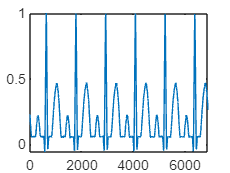

ECG = load("ECG_Data.txt");
subplot(1,1,1)
plot(ECG)

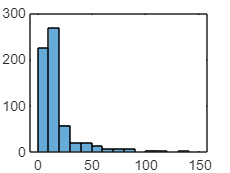

eg=readmatrix('RainFallIndia_Jan.txt');

plot(eg)
histogram(eg)

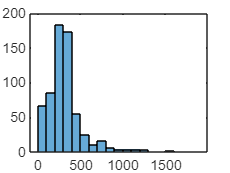

ex=readmatrix('RainFallIndia_July.txt');
plot(ex)
histogram(ex)

fs = 5000; % Sampling frequency in Hz (time resolution of 0.001s)
t = 0:0.001:4.999; % Time vector from 0 to 4.999 seconds

% Frequency values
alpha = 2.0; % Adjust as needed
f1 = 200 * alpha; % Frequency of the first sinusoid (200α Hz)
f2 = 220 * alpha; % Frequency of the second sinusoid (220α Hz)

% Generate the sinusoids
sinusoid1 = sin(2 * pi * f1 * t);
sinusoid2 = sin(2 * pi * f2 * t);

% Combine the sinusoids
combined_signal = sinusoid1 + sinusoid2;

% Normalize the signal to the range [-1, 1]
combined_signal = combined_signal / max(abs(combined_signal));

% Write the combined signal to a .wav file
audiowrite('combined_sinusoids.wav', combined_signal, fs);

% Listen to the combined signal
sound(combined_signal, fs)

fs = 44100; % Sampling frequency in Hz
t = 0:1/fs:1.5; % Time vector for each note (1.5 seconds per note)

% Frequencies for each note (Do, Re, Mi, Fa, So, La, Ti, Do)
frequencies = [261.63, 293.66, 329.63, 349.23, 392.00, 440.00, 493.88, 523.25];

% Initialize an empty signal
combined_signal = zeros(1, length(t) * length(frequencies));

% Generate and append the sinusoidal signals for each note
for i = 1:length(frequencies)
    note_signal = sin(2 * pi * frequencies(i) * t);
    combined_signal(1, (i - 1) * length(t) + 1 : i * length(t)) = note_signal;
end

% Normalize the signal to the range [-1, 1]
combined_signal = combined_signal / max(abs(combined_signal));

% Write the combined signal to a .wav file
audiowrite('melody_sequence.wav', combined_signal, fs);
sound(combined_signal, fs);

textData=load("ConvFile2.txt")

textData =     0.0000
   -0.0000
   -0.0001
   -0.0001
   -0.0002
   -0.0002
   -0.0003
   -0.0003
   -0.0003
   -0.0003


[y,Fs]=audioread('Track003.wav')

y =     0.1351
    0.1443
    0.1452
    0.1451
    0.1652
    0.1836
    0.1632
    0.1314
    0.1407
    0.1778


Fs = 44100

% sound(y,Fs)
normalizedText = textData / max(abs(textData));
convolution_result = conv(y,normalizedText);

% Display the convolution result
disp('Convolution Result:');

Convolution Result:


disp(convolution_result);

    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0001
   -0.0001
   -0.0001
   -0.0002
   -0.0003
   -0.0003
   -0.0004
   -0.0004
   -0.0004
   -0.0005
   -0.0005
   -0.0005
   -0.0005
   -0.0005
   -0.0004
   -0.0003
   -0.0003
   -0.0002
   -0.0001
    0.0000
    0.0001
    0.0002
    0.0003
    0.0003
    0.0003
    0.0003
    0.0003
    0.0002
    0.0001
   -0.0001
   -0.0003
   -0.0005
   -0.0007
   -0.0010
   -0.0012
   -0.0014
   -0.0016
   -0.0017
   -0.0017
   -0.0017
   -0.0015
   -0.0013
   -0.0010
   -0.0006
   -0.0002
    0.0003
    0.0008
    0.0013
    0.0017
    0.0021
    0.0025
    0.0027
    0.0028
    0.0028
    0.0025
    0.0021
    0.0016
    0.0008
   -0.0001
   -0.0011
   -0.0021
   -0.0032
   -0.0043
   -0.0053
   -0.0061
   -0.0067
   -0.0070
   -0.0071
   -0.0067
   -0.0060
   -0.0049
   -0.0034
   -0.0016
    0.0005
    0.0029
    0.0053
    0.0078
    0.0102
    0.0123
    0.0140
    0.0151
    0.0156
    0.0152
    0.0140
    0.0117
    0.0083
    0.0038

audiowrite('convolution_result.wav', convolution_result, fs);
[soun,Fs]=audioread('convolution_result.wav')

soun =          0
   -0.0000
   -0.0000
   -0.0001
   -0.0001
   -0.0001
   -0.0002
   -0.0002
   -0.0003
   -0.0003


Fs = 44100

sound(soun,Fs)